# Numerical Analysis: Assignment 1

## Problem 3 (Taylor Series with Remainder)

`The Maclurien expansion for `$\cos \left(x\right)$`:`


$$\sum_{n=0}^{\infty } {\left(-1\right)}^{n\;} \frac{x^{2n} }{\left(2n\right)!}$$


`By substituting `$x^2$` for `$x$`, it becomes`


$$\sum_{n=0}^{\infty } {\left(-1\right)}^{n\;} \frac{x^{4n} }{\left(2n\right)!}$$


`Therefore,`


$$\int \cos \left(x^2 \right)=\sum_{n=0}^{\infty } {\left(-1\right)}^{n\;} \frac{x^{\left(4n+1\right)} }{\left(4n+1\right)\cdot \left(2n\right)!}$$


exp_arr = [];
% It is good practice to preallocate this array (like in flip function defined below);
% however, this is not applicable here unless you know the number of terms beforehand.
n = 0;
% This is (same) n as in the equations above.
x_min = 0;
x_max = 0.5;
sum = 0;
eps = 0.000001;
% 6 decimal digits of accuracy.

format long
% Specifying data type long for all subsequent values.

while true
    nth_term = (-1)^n / (4*n+1) / fact(2*n) * (x_max^(4*n+1)-x_min^(4*n+1));
    sum = sum + nth_term;
    exp_arr = [exp_arr, sum];
    fprintf('Integral after adding %d Expansion term(s) is %.6f\n', n+1, sum)
    % Output at each iteration; however, if you only want to include valid expansion 
    % terms, put this command after the if statement as the (commented) command below.
    if n > 0 && abs(exp_arr(n+1)-exp_arr(n)) < eps
        fprintf(['\x2235 |T(n+1)-T(n)| < \x3B5\n\x2234 %d expansion terms are suffic' ...
            'ient to achieve 6 decimal digits of accuracy.\nThen, the definite integ' ...
            'ral of cos(x^2) from 0 to 0.5 is %.6f'], n, exp_arr(n))
        break;
    end
    %fprintf('Expansion term no. %d is %.6f \n', n+1, sum)
    n = n + 1;
end

Integral after adding 1 Expansion term(s) is 0.500000
Integral after adding 2 Expansion term(s) is 0.496875
Integral after adding 3 Expansion term(s) is 0.496884
Integral after adding 4 Expansion term(s) is 0.496884


∵ |T(n+1)-T(n)| < ε
∴ 3 expansion terms are sufficient to achieve 6 decimal digits of accuracy.
Then, the definite integral of cos(x^2) from 0 to 0.5 is 0.496884

% One can also output all the data at the end as such
terms  = sprintf('%.6f\n', exp_arr(1:n)');
fprintf(['The %d expansions give \n%sand so, the integral of cos(x^2) from 0 to 0.5 ' ...
    'is %.6f up to an accuracy of six decimal places.'], n, terms, exp_arr(n))

The 3 expansions give 
0.500000
0.496875
0.496884
and so, the integral of cos(x^2) from 0 to 0.5 is 0.496884 up to an accuracy of six decimal places.

## Problem 4 (Polynomial Interpolation)

`Data Points:`


$$x_i =\left\lbrack \begin{array}{cccc}
0 & 5 & 10 & 15
\end{array}\right\rbrack$$



$$y_i =\left\lbrack \begin{array}{cccc}
3 & 8 & -1 & 9
\end{array}\right\rbrack$$


x_i = [0, 5, 10, 15];
y_i = [3, 8, -2, 9];

% Just for display purposes (aesthetics). You can also depict them in tables as such
%table(x_i, y_i)
%table([0; 3], [5; 8], [10; -2], [15; 9], 'RowNames',{'x_i', 'y_i'})

#### `a) Solving a System of Linear Equations:`

`Let `$P_3 \left(x\right)=a_3 x^3 +a_2 x^2 +a_1 x+a_0$


$$\therefore P_3(0)=a_0=3$$



$$P_3 \left(5\right)=125\;a_3 +25\;a_2 +5\;a_1 +a_0 =8$$



$$P_3 \left(10\right)=1000\;a_3 +100\;a_2 +10\;a_1 +a_0 =-2$$



$$P_3 \left(15\right)=3375\;a_3 +225\;a_2 +15\;a_1 +a_0 =9$$


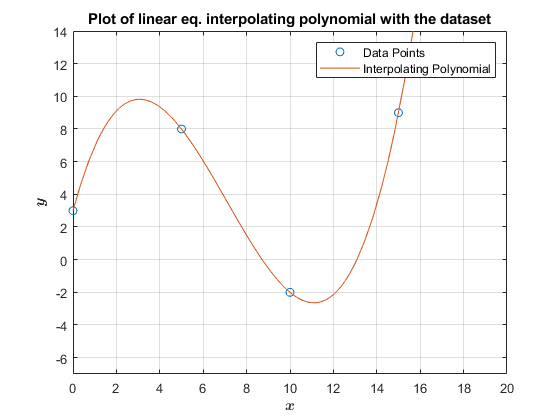

% System of Linear Equations:
poly_deg = length(x_i)-1;
van_der_Monde = ones(length(x_i));
% Construct van der Monde matrix.
for i = 2:length(x_i)
  van_der_Monde(:, i) = x_i.' .* van_der_Monde(:, i-1);
end
a = van_der_Monde\y_i.';
p = flip(a);
% one can reverse the order of elements in a vector easily through running
% a for-loop on the indices in decreasing order and assigning each
% corresponding value in a new vector/variable. This is so trivial to do!

figure(1)
plot(x_i.', y_i.', 'o', 'DisplayName', 'Data Points')
hold on
fplot(@(t) polyval(p, t), [0 max(x_i)+1], '-', 'DisplayName', 'Interpolating Polynomial')
% You can put "a(4)*t^3+a(3)*t^2+a(2)*t+a(1)" instead of the polyval command if this is 
% considered a ready-made package. My choice to do so is to properly vectorize the code.
hold off

title('Plot of linear eq. interpolating polynomial with the dataset')
graphformat(x_i, y_i)

#### `b) Lagrange Form of the Interpolation Polynomials:`


$$l_i \left(x\right)=\prod_{j=0,\;i\not= j}^n \left(\frac{x-x_j }{x_i -x_j }\right)$$


`where `$n=3$` in this case. Then,`


$$P_3 \left(x\right)=\sum_{i=0}^3 l_i \left(x\right)\cdot y_i$$



$$\begin{array}{l}
l_0 \left(x\right)=\frac{\left(x-x_1 \right)}{\left(x_0 -x_1 \right)}\frac{\left(x-x_2 \right)}{\left(x_0 -x_2 \right)}\frac{\left(x-x_3 \right)}{\left(x_0 -x_3 \right)},\;l_1 \left(x\right)=\frac{\left(x-x_0 \right)}{\left(x_1 -x_0 \right)}\frac{\left(x-x_2 \right)}{\left(x_1 -x_2 \right)}\frac{\left(x-x_3 \right)}{\left(x_1 -x_3 \right)}\\
l_2 \left(x\right)=\frac{\left(x-x_0 \right)}{\left(x_2 -x_0 \right)}\frac{\left(x-x_1 \right)}{\left(x_2 -x_1 \right)}\frac{\left(x-x_3 \right)}{\left(x_2 -x_3 \right)},\;l_3 \left(x\right)=\frac{\left(x-x_0 \right)}{\left(x_3 -x_0 \right)}\frac{\left(x-x_1 \right)}{\left(x_3 -x_1 \right)}\frac{\left(x-x_2 \right)}{\left(x_3 -x_2 \right)}
\end{array}$$


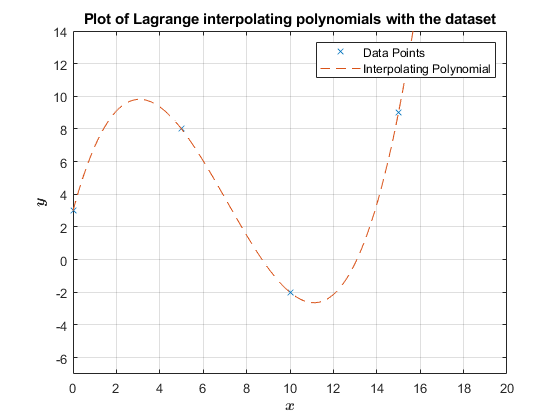

% Lagrange Form:
x = linspace(min(x_i), max(x_i)+1);
% This is a vector of points where the interpolation will be evaluated. The
% use of max and min throughout the code is just for aesthetics and generality.
l = ones(length(x_i), length(x));
y = zeros(1,100);
% As the default argument for linspace creates 100 data points.
for i = 1:length(x_i)
    for j = 1:length(x_i)
        if i ~= j
            l(i,:) = l(i,:).*(x-x_i(j))/(x_i(i)-x_i(j));
        end
    end
    y = y + y_i(i)*l(i,:);
    % This will produce a vector of interpolation points for all x after the loop ends.
    % This acts as a Fourier series of sorts. Adjusting y for each x at each iteration.
end

figure(2)
plot(x_i.',y_i.','x', 'DisplayName', 'Data Points')
hold on
plot(x, y, '--', 'DisplayName', 'Interpolating Polynomial')
hold off

title('Plot of Lagrange interpolating polynomials with the dataset')
graphformat(x_i, y_i)

## Bonus Problem (Splines)

$L\left(x\right)$` consists of piecewise polynomials of degree `$\le 1$` (i.e., linear) as`


$$L\left(x\right)\doteq \left\lbrace \begin{array}{ll}
\underset{\vdots }{L_0 \left(x\right),}  & t_0 \le x\le t_1 \\
L_{n-1} \left(x\right) & t_{n-1} \le x\le t_n 
\end{array}\right.$$


`where `$t$` are the knots (x-coordinates of the data points)`


$$t=x_i =\left\lbrack \begin{array}{cccc}
0 & 5 & 10 & 15
\end{array}\right\rbrack$$


`and `$L\left(x\right)$` is zero-time continuously differentiable (i.e., continuous function):`


$$L_0 \left(t_0 \right)=y_0 =a_0 =3$$


`as `$x_0 =0$


$$L_\left(i-1\right)(t_i)=L_i(t_i)=y_i=a_i+b_ix_i,\quad i=1,2,\cdots,n-1$$



$$L_{\left(n-1\right)} \left(t_n \right)=y_n =a_n +b_n x_n =9$$


`where `$y=y_i =\left\lbrack \begin{array}{cccc}
3 & 8 & -2 & 9
\end{array}\right\rbrack$


$$\therefore L_i(x)=y_i+\frac{y_\left(i+1\right)-y_i}{t_\left(i+1\right)-t_i}(x-t_i),\quad i=0,1,\cdots,n-1$$


`where `$n=3$` in this case. Thus, one obtains:`


$$L_0(x)=3+x,\quad L_1(x)=18-2x,\quad L_2=-24+2.2x$$


`Hence, the conditions `$L\left(x\right)$` has to satisfy:`

- `The linearity condition in which each `$L\left(x\right)$` forms a straight line between the knots.`

- `The continuity conditions:`


$$3+x=18-2x\;,\exists x=5$$


$18-2x=-24+2\ldotp 2x,\;\exists x=10$`.`

x = 12;
% User can be prompted to choose the value of x as such
%x = input("Please input the data point where the linear spline is to be evaluated: ")
if x < x_i(1) || x > x_i(length(x_i))
    fprintf('The value of x (%d) is not valid; x must be between %.1f and %.1f', x, ...
        min(x_i), max(x_i))
    %x = input("Enter a valid x where the linear spline is to be evaluated: ")
elseif x == x_i(length(x_i))
    L = x_i(length(x_i));
    fprintf('The value of L(%d) is %.2f', x, L)
else
    for i = 1:length(x_i)-1
        if x == x_i(i)
            L = y_i(i)
        elseif x > x_i(i) && x < x_i(i+1)
            L = y_i(i) + (y_i(i+1)-y_i(i))/(x_i(i+1)-x_i(i))*(x-x_i(i));
        end
    end
    fprintf('The value of L(%d) is %.2f', x, L)
end

The value of L(12) is 2.40

% Please note that this code is for a single-number evaluation. You can
% vectorize it easily: make x into an array and compute L for each element.

function f = fact(num)
% Factorial of number "num".
%
%   Input: num, any number belonging to N
%   Output: fact, the factorial of said number
%
%See also factorial.

if num ~= 0
    f = 1;
    for i = 1:num
        f = f*i;
    end
else
    f = 1;
end
end

function cev = flip(vec)
% Nontheless, here it is. This reverses the order of elements in vector
% arrays. This can be deleted as the function "flip" is already a MATLAB
% defined function.
%
%   Input: vec, any vector
%   Output: cev, inverse of said vector (pun intended)
%
%See also flip.

cev = zeros(length(vec),1);
% Said preallocating as the vector size is known here.
count = 1;
for i = length(vec):-1:1
    cev(count) = vec(i);
    count = count+1;
end
end

function graphformat(x_data, y_data)
% Again, aesthetics!
%
%   Input: x_data, y_data
%
%See also grid, legend.

grid
legend
xlim([min(x_data) max(x_data)+5])
ylim([min(y_data)-5 max(y_data)+5])
xlabel('{\boldmath$x$}','Interpreter','latex');
ylabel('{\boldmath$y$}','Interpreter','latex');
end